# **整体优化**

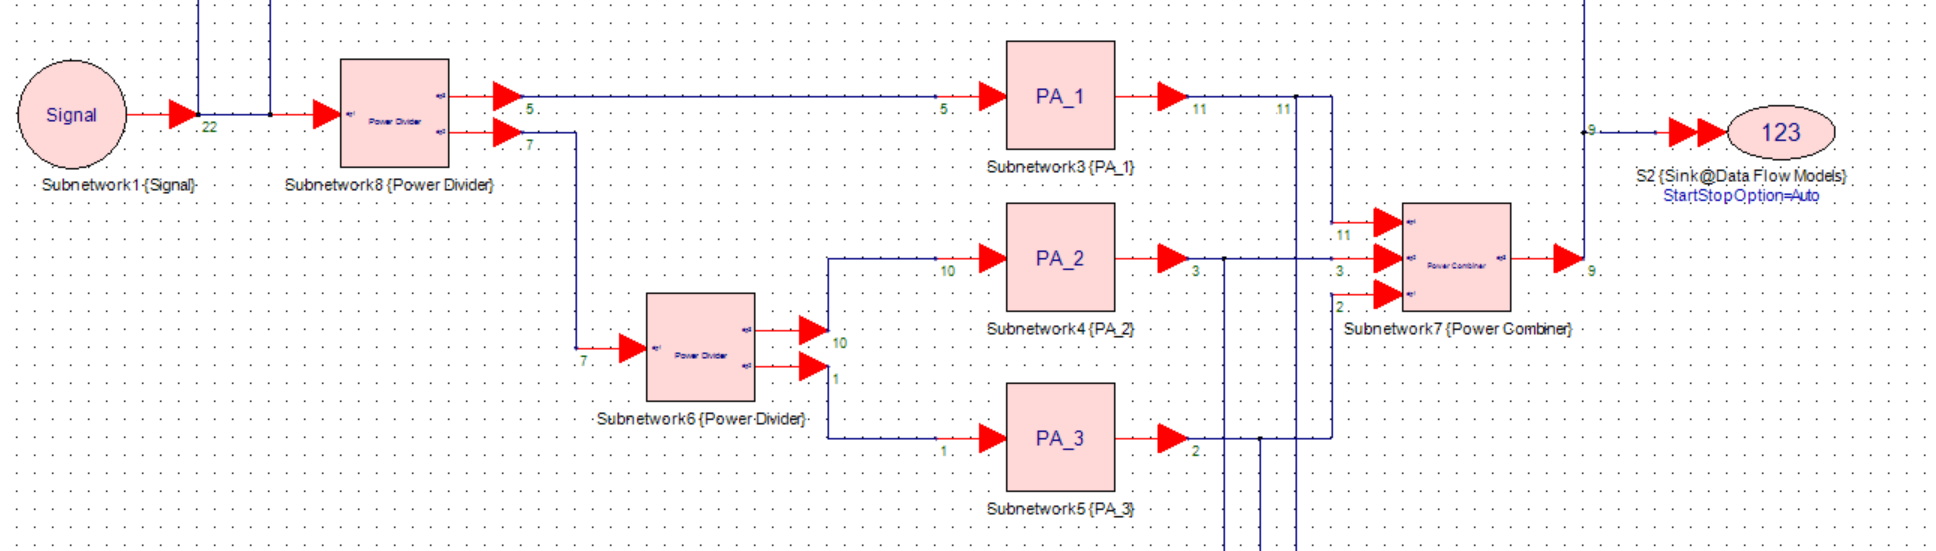

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Train System----------------------------

此模型是完全固定的！

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[A1_input,A23]=Power_Divider(Sys_input);
[A2_input,A3_input]=Power_Divider(A23);
A1_output=PA_1(A1_input);
A2_output=PA_2(A2_input);
A3_output=PA_3(A3_input);
Original_output_sim=Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
err=abs(Original_output_sim-Original_output) %模型本身的误差

err = 1.0e-14 *

    0.0171
    0.0450
    0.0623
    0.0124
    0.0056
    0.0395
    0.0420
    0.0776
    0.0072
    0.0168


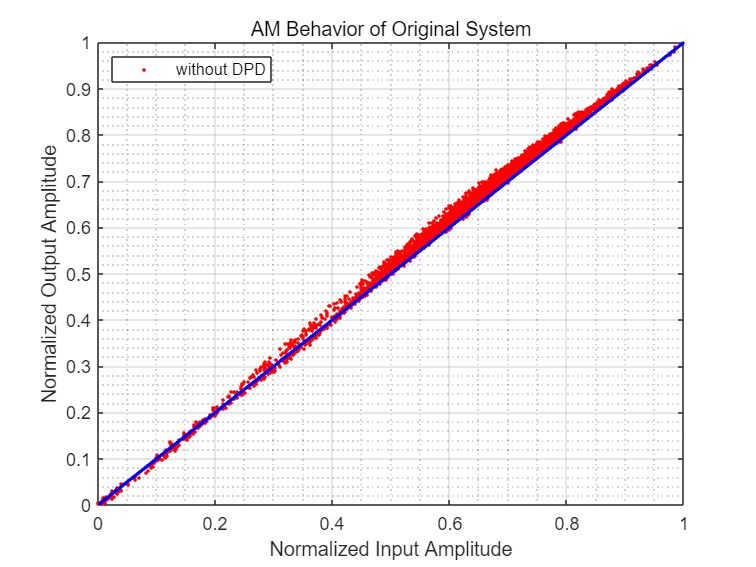

Plot_AM(Sys_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Sys_input,Original_output_sim);
nmse_act = NMSE_dB(Sys_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -26.743435 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -26.743435 dB


## -----------------------------Valid System----------------------------

此模型是完全固定的！

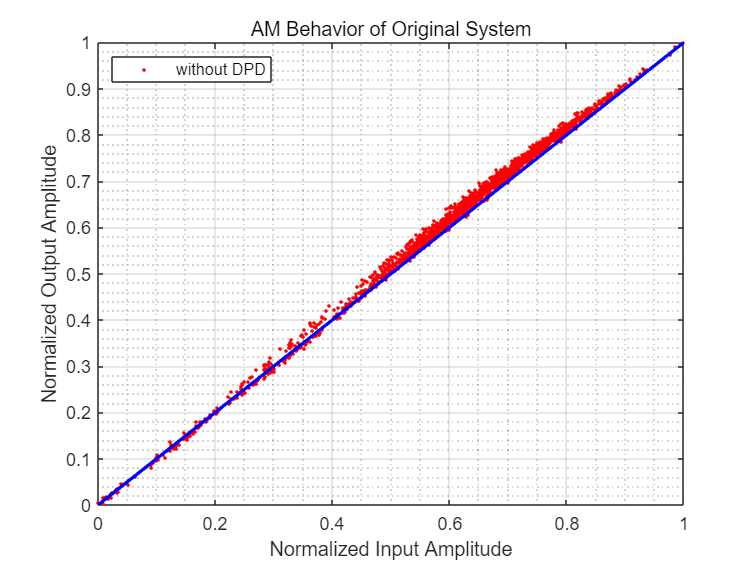

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[A1_input,A23]=Power_Divider(Sys_input);
[A2_input,A3_input]=Power_Divider(A23);
A1_output=PA_1(A1_input);
A2_output=PA_2(A2_input);
A3_output=PA_3(A3_input);
Original_output_sim=Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA的延时，所以少算四个值
Sys_input_sim=Sys_input(5:end);
Original_output_sim=Original_output_sim(5:end);
% 性能评估
% err=abs(Original_output_sim-Original_output) %模型本身的误差
Plot_AM(Sys_input_sim,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim = NMSE_dB(Sys_input_sim,Original_output_sim);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -26.794185 dB
